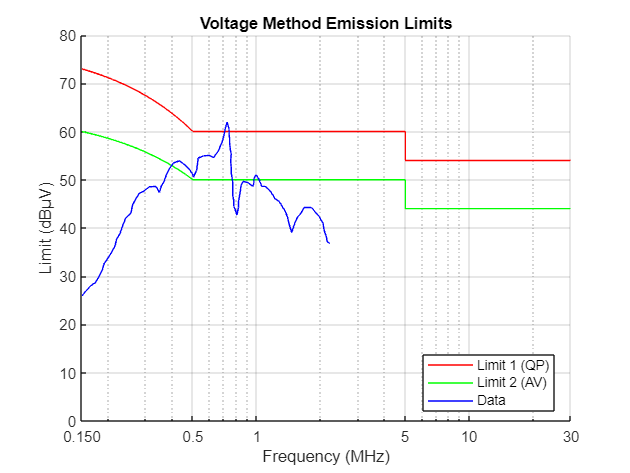

% Define the frequency points
freq_kHz = [150, 500, 5000, 30000];

% Define the QP and AV limits for these points
QP_limits = [73, 60, 54, 54];  % Decline from 73 to 60, then constant
AV_limits = [60, 50, 44, 44];  % Decline from 60 to 50, then constant

% Calculate the linear coefficients for 150 kHz to 500 kHz
% QP
a_QP = (QP_limits(2) - QP_limits(1)) / (freq_kHz(2) - freq_kHz(1));
b_QP = QP_limits(1) - a_QP * freq_kHz(1);
% AV
a_AV = (AV_limits(2) - AV_limits(1)) / (freq_kHz(2) - freq_kHz(1));
b_AV = AV_limits(1) - a_AV * freq_kHz(1);

% Define detailed frequency range for interpolation
freq_interp_1 = 150:1:500;
freq_interp_2 = 500:10:5000;
freq_interp_3 = 5000:100:30000;

% Interpolate the limits
% QP_interp_1 = linspace(73, 60, length(freq_interp_1));
QP_interp_1 = a_QP * freq_interp_1 + b_QP;
QP_interp_2 = 60 * ones(1, length(freq_interp_2));
QP_interp_3 = 54 * ones(1, length(freq_interp_3));

% AV_interp_1 = linspace(60, 50, length(freq_interp_1));
AV_interp_1 = a_AV * freq_interp_1 + b_AV;
AV_interp_2 = 50 * ones(1, length(freq_interp_2));
AV_interp_3 = 44 * ones(1, length(freq_interp_3));

% Concatenate all interpolated data
freq_full = [freq_interp_1, freq_interp_2, freq_interp_3];
QP_full = [QP_interp_1, QP_interp_2, QP_interp_3];
AV_full = [AV_interp_1, AV_interp_2, AV_interp_3];

% %Generate dataset points 
% freq_32_Q_B = linspace(150, 30000, 500); % Frequency points
% data_32_Q_B = 50 + 10 * sin(0.01 * freq_32_Q_B) + randn(size(freq_32_Q_B)) * 3; % Sample data with noise

% Plotting
figure;
hold on;

% Plot Quasi-Peak (QP) limits
plot(freq_full, QP_full, 'r');
% Plot Average (AV) limits
plot(freq_full, AV_full, 'g');
%plot datas set
plot(x*1000,y, 'b');  
% Adding labels and title
xlabel('Frequency (MHz)');
ylabel('Limit (dBμV)');
title('Voltage Method Emission Limits');
legend('Limit 1 (QP)', 'Limit 2 (AV)','Data', 'Location', 'Best');

% Set the x-axis to logarithmic scale
set(gca, 'XScale', 'log');
xlim([150 30000]);
ylim([0 80]);

% Adding specific x-ticks
set(gca, 'XTick', [150, 500, 1000, 5000, 10000, 30000]);
set(gca, 'XTickLabel', {'0.150', '0.5', '1', '5', '10', '30'});
grid on;
hold off;